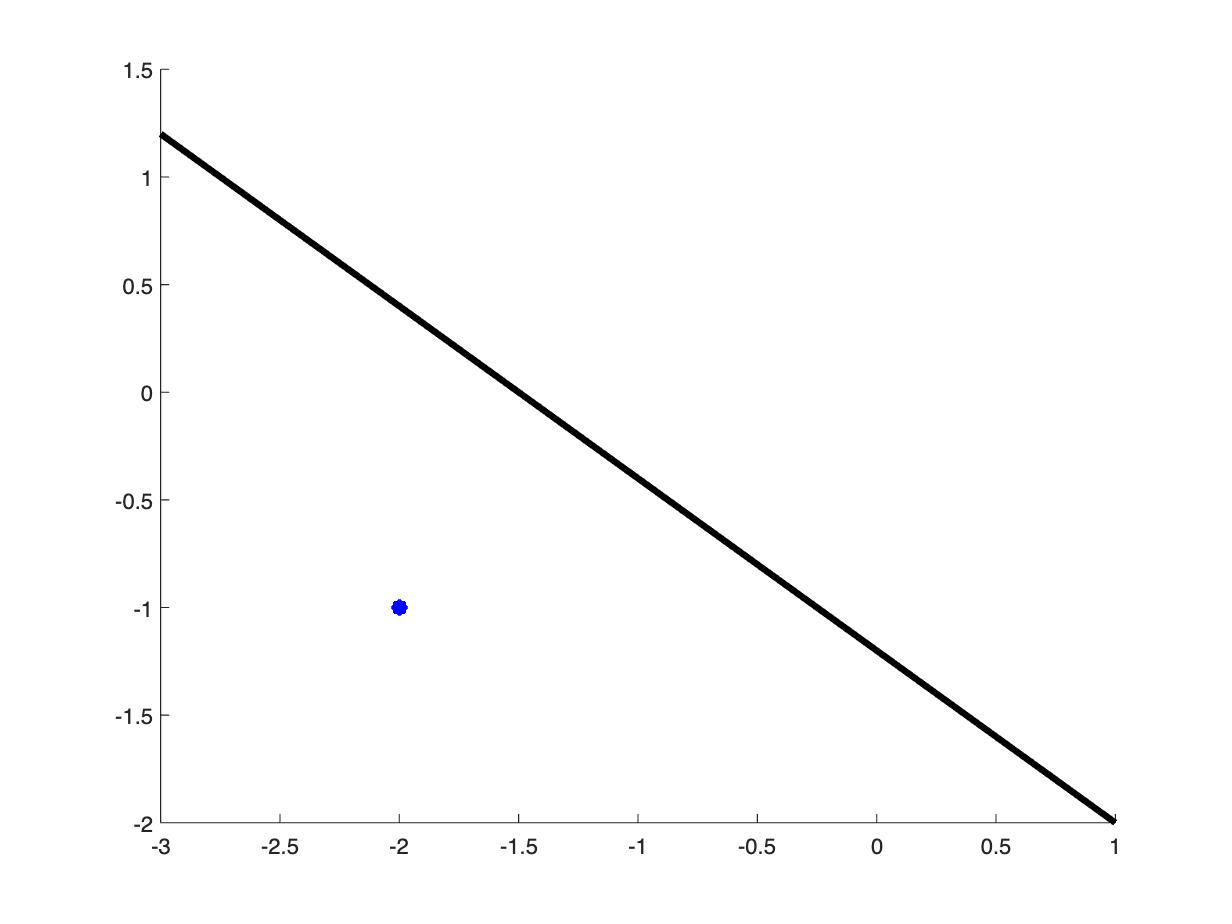

clf;
v1 = [1,2,1];
F = [1,2,3;
     4,5,6;
     7,8,9];
v2 = [-2,-1,1];

x = linspace(-3,1,1000);
y = fund(v1,F,x);

hold on
plot(x,y,"k",'LineWidth',3)
plot(v2(1),v2(2),'b*', 'LineWidth',5)

print(dist2line([1,fund(v1,F,1),1],[0,fund(v1,F,0),1],v2))

Error using checkArgsForHandleToPrint
Handle input argument contains nonhandle values.
Error in checkArgsForHandleToPrint

Error in print>LocalCreatePrintJob (line 101)
handles = checkArgsForHandleToPrint(0, varargin{:});
Error in print (line 38)
[pj, inputargs] = LocalCreatePrintJob(varargin{:});

function dist = dist2line(p_line_1, p_line_2, p)
    a = p_line_1 - p_line_2;
    b = p - p_line_1;
    dist = norm(cross(a,b)) / norm(a);
end

function y = fund(v, F, x)
    a = (F(1,1)*v(1)) + (F(2,1)*v(2)) + (F(3,1)*v(3));
    b = (F(1,2)*v(1)) + (F(2,2)*v(2)) + (F(3,2)*v(3));
    c = (F(1,3)*v(1)) + (F(2,3)*v(2)) + (F(3,3)*v(3));
    y = ((-x.*a) - (c)) / (b);
    return
end
